Overview of several tables

lab.User

ans = Object lab.User

 ::  ::

      USER_ID          full_name                   email                 phone         carrier          slack          contact_via     presence      primary_tech    tech_responsibility                                     slack_webhook                                                                                 watering_logs                                                 day_cutoff_time
    ___________    __________________    _________________________    ____________    _________    ________________    ___________    ___________    ____________    ___________________

subject.Subject

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'ben'        'B205'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES-CRE'            ''                   27             '=BLOB='    
    'ben'        'B208'           NaN        'Male'    ''     'vivarium'     '1910'     'DAT-IRES

subject.Subject & 'user_id="edward"'

ans = Object subject.Subject

 ::  ::

    USER_ID     SUBJECT_ID    genomics_id      sex       dob     location     protocol      line       subject_description    initial_weight    head_plate_mark
    ________    __________    ___________    ________    ___    __________    ________    _________    ___________________    ______________    _______________

    'edward'      'E18'           NaN        'Male'      ''     'valhalla'     '1910'     'Unknown'            ''                    26            '=BLOB='    
    'edward'      'E26'           NaN        'Male'      ''     'vivarium'     '1910'     'Unknown'       

action.Weighing

ans = Object action.Weighing

 ::  ::

    USER_ID    SUBJECT_ID        WEIGHING_TIME        weigh_person       location        weight    weight_notice
    _______    __________    _____________________    ____________    _______________    ______    _____________

     'ben'       'B205'      '2018-06-20 12:52:00'      'ben'         'pni-174cr4jk2'       26          ''      
     'ben'       'B205'      '2018-06-21 16:53:00'      'ben'         'pni-174cr4jk2'     25.5          ''      
     'ben'       'B205'      '2018-06-23 04:39:00'      'ben'         'pni-174cr4jk2'       25          ''      
     'ben'       'B205'      '2018-06-24 21:22:00'      'ben'         'pni-174cr4jk2'       26          ''      
     'ben'       'B205'      '2018-06-25 15:

action.Weighing & 'user_id="edward"' & 'subject_id="E76"'

ans = Object action.Weighing

 ::  ::

    USER_ID     SUBJECT_ID        WEIGHING_TIME        weigh_person       location        weight    weight_notice
    ________    __________    _____________________    ____________    _______________    ______    _____________

    'edward'      'E76'       '2018-08-23 15:26:00'    'sstein'        'pni-174cr4jk2'     27.4          ''      
    'edward'      'E76'       '2018-08-24 15:18:00'    'sstein'        'pni-174cr4jk2'     26.4          ''      
    'edward'      'E76'       '2018-08-25 15:27:00'    'sstein'        'pni-174cr4jk2'     25.8          ''      
    'edward'      'E76'       '2018-08-26 13:15:00'    'sbaptista'     'pni-174cr4jk2'     25.6          ''      
    'edward'      'E76'       '2018-08

action.WaterAdministration & 'user_id="edward"' & 'subject_id="E47"'

ans = Object action.WaterAdministration

 ::  ::

    USER_ID     SUBJECT_ID    ADMINISTRATION_DATE    earned    supplement    received    watertype_name
    ________    __________    ___________________    ______    __________    ________    ______________

    'edward'      'E47'          '2017-08-02'            0          1             1        'Unknown'   
    'edward'      'E47'          '2017-08-03'         1.11          0          1.11        'Unknown'   
    'edward'      'E47'          '2017-08-04'         1.26          0          1.26        'Unknown'   
    'edward'      'E47'          '2017-08-07'            0        1.5           1.5        'Unknown'   
    'edward'      'E47'          '2017-08-08'          1.2          0           1.2    

subj = fetch(subject.Subject & 'user_id="edward"' & 'subject_id="E47"')

subj = struct with fields:
       user_id: 'edward'
    subject_id: 'E47'


Earned water as a function of date.

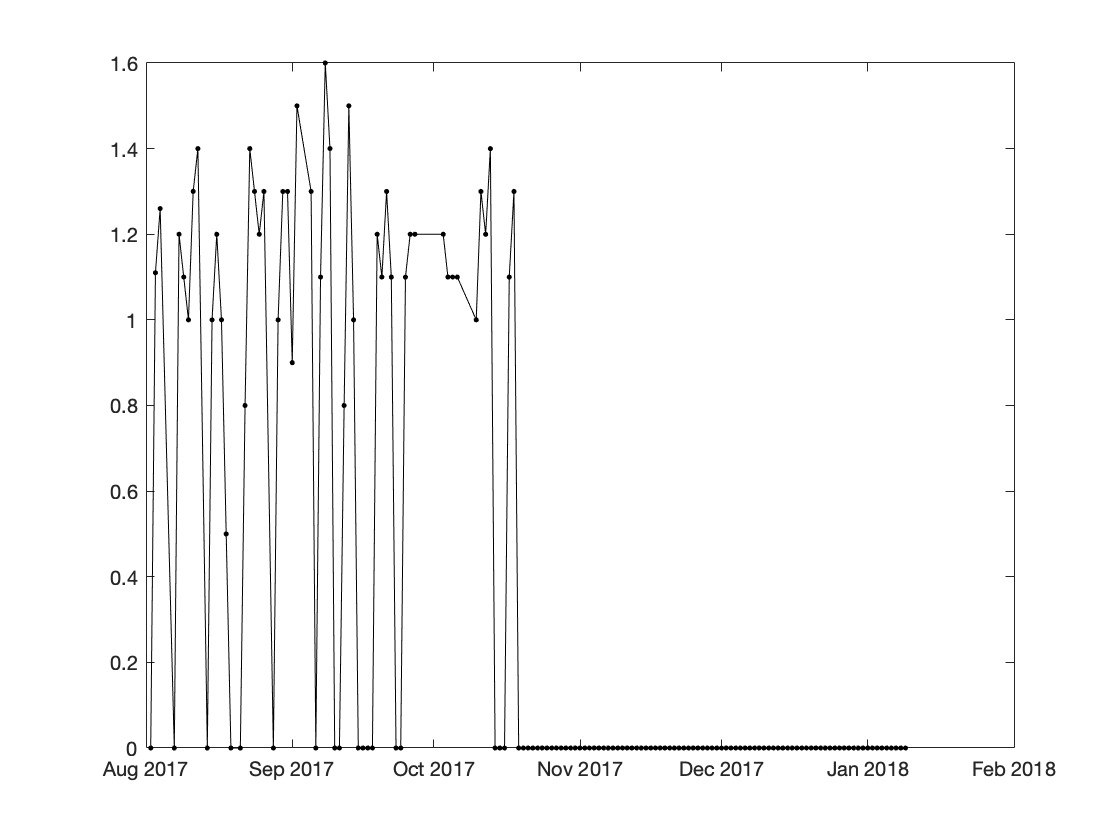

[water_date, earned_water] = fetchn(action.WaterAdministration & subj, 'administration_date', 'earned');
water_date = datetime(water_date);
figure; plot(water_date, earned_water, 'k.-')

Weight as a function of date.

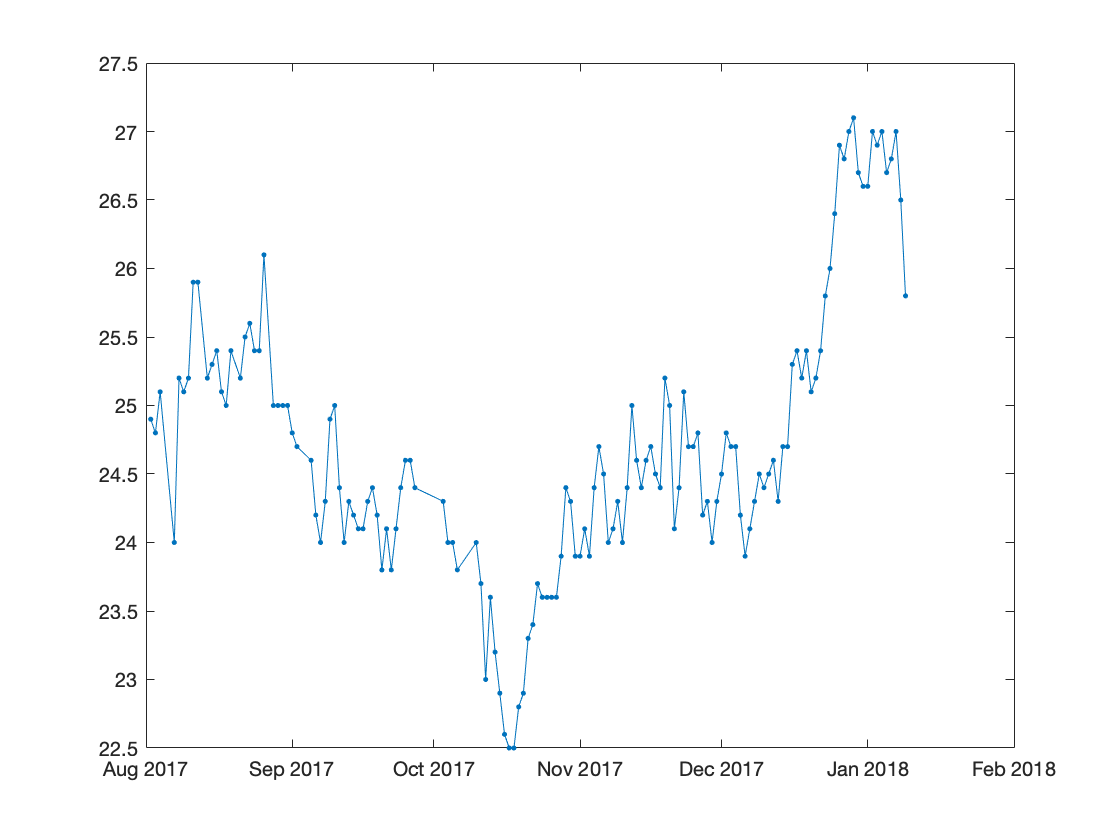

[weighing_date, weight] = fetchn(...
    action.Weighing & subj, 'DATE(weighing_time)->weighing_date', 'weight');
weighing_date = datetime(weighing_date);
figure; plot(weighing_date, weight, '.-')

Plot both together:

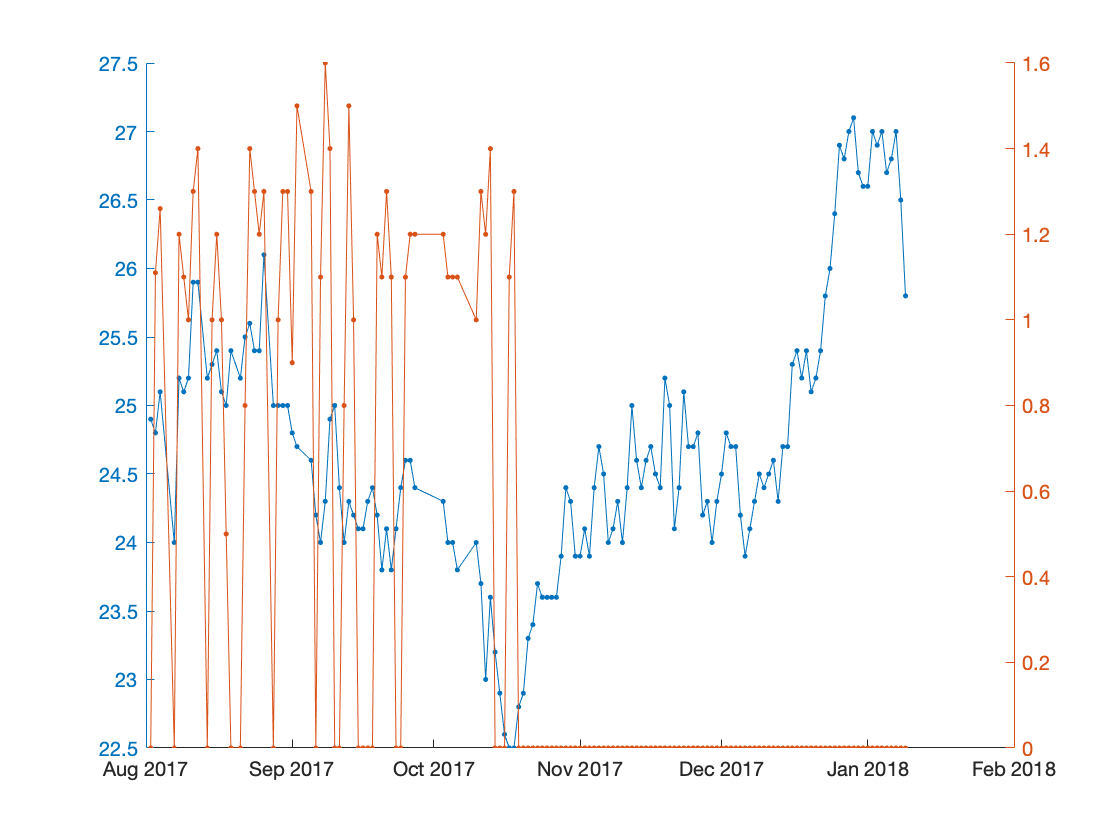

figure; hold on
yyaxis left
plot(weighing_date, weight, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

acquisition.Session

ans = Object acquisition.Session

 ::  ::

    USER_ID    SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative
    _______    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________    _______________    ____________</

acquisition.Session & subj

ans = Object acquisition.Session

 ::  ::

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative
    ________    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________    _______________    ____________

Plot performance as a function of date.

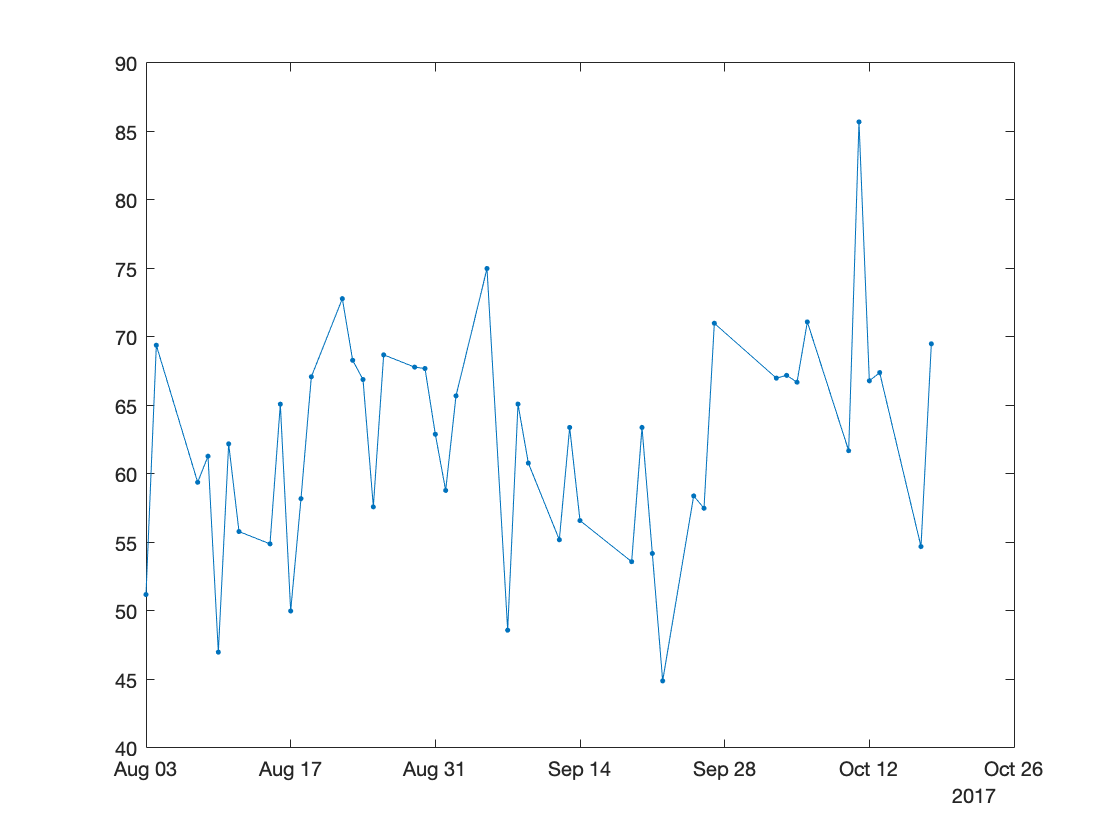

[session_date, performance] = fetchn(acquisition.Session & subj, 'session_date', 'session_performance');
session_date = datetime(session_date);
figure; plot(session_date, performance, '.-')

Plot both performance and earned water as a function of date.

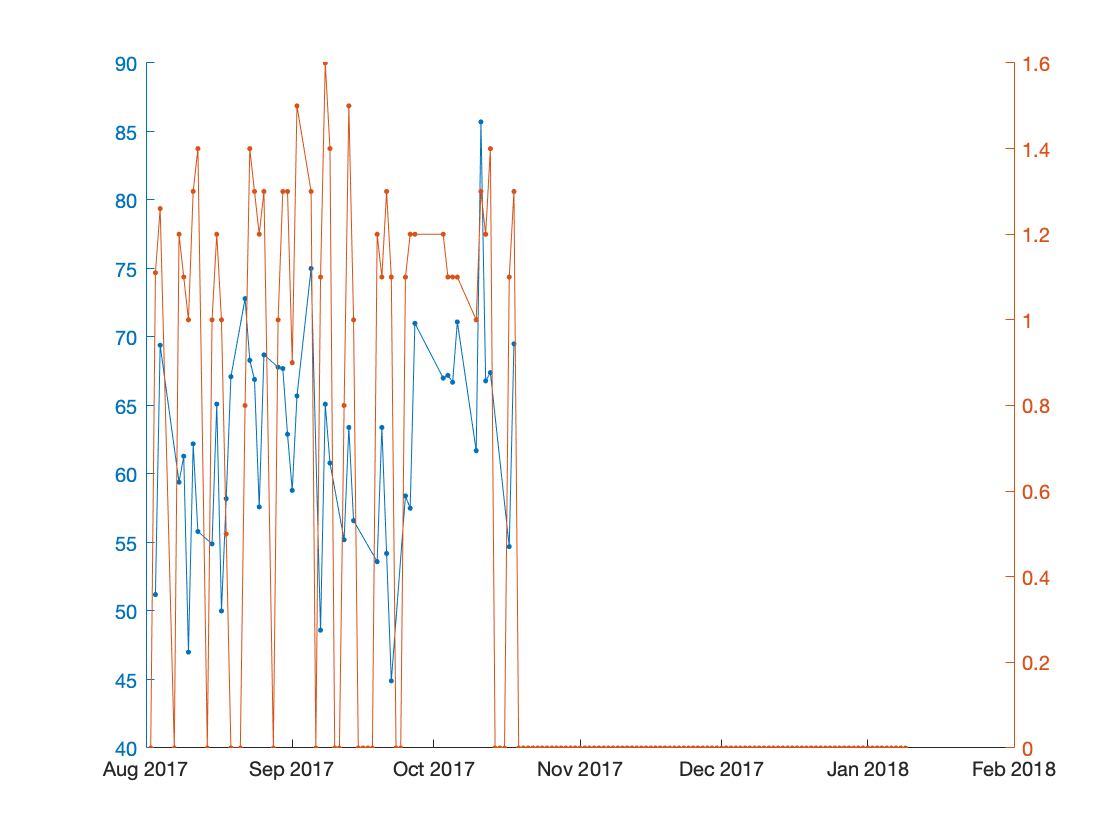

figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Compute trial numbers of a given date.

acquisition.TowersBlockTrial & subj & 'session_date="2017-08-03"'

ans = Object acquisition.TowersBlockTrial

 ::  ::

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER    BLOCK    TRIAL_IDX    trial_type    choice    trial_abs_start    trial_duration    excess_travel    i_arm_entry    i_blank    i_cue_entry    i_mem_entry    i_turn_entry    iterations    trial_id    trial_prior_p_left    vi_start    trial_time    collision    cue_presence_left    cue_presence_right    cue_onset_left    cue_onset_right    cue_offset_left    cue_offset_right    cue_pos_left 

Compute trial numbers of each date

query = acquisition.Session & subj

query = Object acquisition.Session

 ::  ::

    USER_ID     SUBJECT_ID    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time        location       task      level    set_id    stimulus_bank    stimulus_commit    stimulus_set    ball_squal    session_performance    session_narrative
    ________    __________    ____________    ______________    _____________________    _____________________    __________    ________    _____    ______    _____________    _______________    __________

[session_date, n_trials] = fetchn(query.aggr(acquisition.TowersBlockTrial, 'count(*) -> n'), 'session_date', 'n');
session_date = datetime(session_date);

figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')